# P04: Funciones de membresía

## **Integrantes:**

- **Arellano Paz Ángel Ulises **

- **García Arteaga Alejandro **

- **Pérez Aboytes David **

- **Quijano Gutiérrez Luis Humberto **

- **Soto García Pablo Yael **

## **Contenido**

- **Objetivos**

- **Introducción**

- **Problema 1**

- **Problema 2**

- **Problema 3**

- **Problema 4**

- **Problema 5**

- **Problema 6**

- **Problema 7**

- **Problema 8**

- **Problema 9**

- **Problema 10**

- **Problema 11**

- **Problema 12**

- **Bibliografia**

## Objetivos

- Implementar operaciones de conjuntos difusos, utilizando MATLAB

- Implementar transformaciones de conjuntos difusos, utilizando MATLAB

## Introducción

## Conjuntos difusos:

Los conjuntos difusos son elementos que tienen una función de membresía, la cual representa un grado de pertenencia que se encuentra entre “1 y 0”, esto nos permite decir que un elemento x ϵ A con un cierto grado de certeza. Con estos conjuntos difusos se pueden hacer operaciones de unión, intersección, complemento, etc. Y se comportan de igual manera que un conjunto clásico a excepción de “tercero excluido y contradicción”, de estas operaciones se tienen resultados diferentes a los obtenidos con conjuntos clásicos.

En algunos casos, cuando no se tienen valores exactos y precisos, se debe tener una incertidumbre la cual nos permite considerar un valor que no es exacto como bueno, siempre y cuando este se encuentre dentro de la incertidumbre. Gracias a esto podemos modelar (graficar) nuestras percepciones de la realidad, por ejemplo, la altura (como considerar si alguien es alto o bajo) o la belleza, etc.

### Problema 1

Investiga la expresión matemática para la función  smf y la función psigmf. Reporta dichas expresiones 

**SMF:**

Esta funcion calcula valores difusos de membresia usando una función de membresía en forma de S basada en spline.

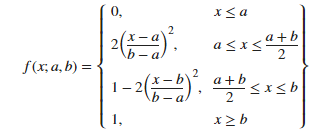

**PSIGMF:**

Esta funcion calcula valores difusos usando una funcion de membresia signoidal.

### **Problema 2**

Cree una función en matlab que reciba como argumentos de entrada el dominio y el rango de una función de membresía, esta función debe crear la grafica del conjunto difuso con una edición de tu preferencia (no queremos repetir los códigos para gráficar cada vez que se quiera visualizar un conjunto difuzo, como se ha visto previamente).

Prueba el código con las dos funciones del problema anterior, los parámetros que debes utilizar  (debes investigar) son los que se usan en el ejemplo de la práctica. 

Se espera esta sección dos llamadas a la función con las dos gráficas respectivas. 

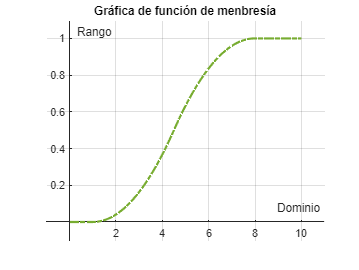

%Se declara el dominio y el rango dados por el ejemplo
%smf
x = 0:0.1:10;
y = smf(x,[1 8]);

%psigmf
x2 = 0:0.1:10;
y2 = psigmf(x,[2 3 -5 8]);


%Se manda a llamar la función para cada ejemplo
p02(x,y)

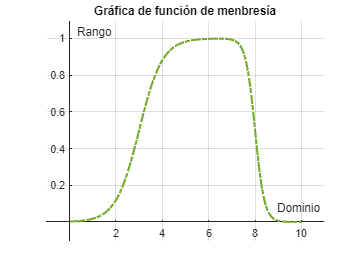

p02(x2,y2)

### **Problema 3 **

Repite el problema anterior pero para conjuntos difusos en tiempo discreto.  

Prueba esta función con los conjuntos difusos (A, B) de la imagen 5 (OperDif5). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso.

Se espera esta sección dos llamadas a la función con las dos gráficas respectivas. 

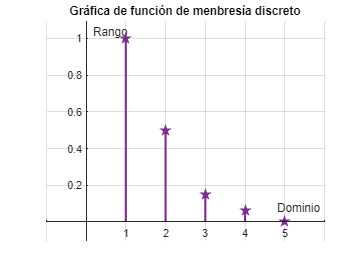

%Se definen los conjuntos A y B
A = [1/1.0 0.75/1.5 0.3/2.0 0.15/2.5 0/3.0];
B = [1/1.0 0.6/1.5 0.2/2.0 0.1/2.5 0/3.0];

%Se manda a llamar la función para cada conjunto
p03(A)

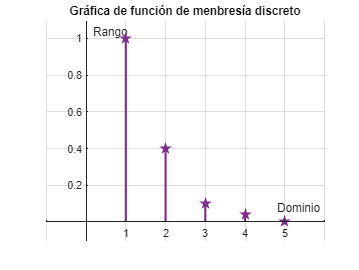

p03(B)

### **Problema 4**

Elabora una función que reciba el conjunto dominio x y el rango A de un conjunto difuso. Un parámetro adicional que indique el tipo de complemento que se quiere hacer (estándar, Sugeno, Yager). La función debe regresar el rango de valores del conjunto resultante C. Además de imprimir una figura (2 por 1) donde se muestren las grafica de los dos conjunto involucrados.

Prueba esta función con el inciso a) de la imagen 4 (OperDif4). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso. Para esto:

- Reporta los tres tipos de complementos (si no puedes implentar esto es una solo función crea tres funciones de complemento difuso)

- Combina las herramientas que ya tienes desarrolladas (de ser posible) para mostrar una gráfica con los tres tipos de complementos o desarrolla esta gráfica sin utilizar tus herramientas

En esta sección se espera tres llamadas a la función y un código para generar la cuarta gráfica. 

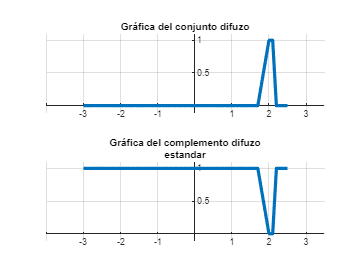


% Se define a las variables y al conjunto
syms x2;
a=1.7;
b=2;
c=2.2;
M(x2) = piecewise(x2<=a, 0 , (a<x2)&(x2<=b),(x2-a)./(b-a),(b<x2) & (x2<=c),(c-x2)./(x2-b),c<x2,0);
% Se define una un dominio x para no tener confusion con los codigos
x=-3:0.1:2.5;
%Se llama a la funcion
% El tercer parametro es el tipo de complemento: estandar, sugeno y yeger
% respectivamente
C1=complementoDifuso(x,M(x),1);

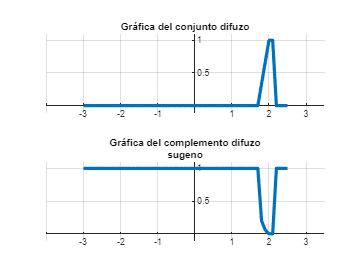

C2=complementoDifuso(x,M(x),2,7);

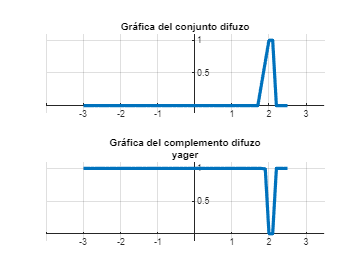

C3=complementoDifuso(x,M(x),3,7);

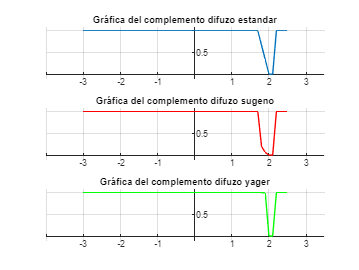

%%
% Para el siguiente punto 

e=1.-M(x);

su=((1.-M(x))./(1.+(7.*M(x))));

y=(1-(M(x).^7)).^(1/7);

figure

subplot(3,1,1)
        plot(x, e,'LineWidth',0.5)
        grid on
        axis([min(x)-1,max(x)+1,-0.1,1.1])
        title('Gráfica del complemento difuzo estandar')
        h = gca;                             % ejes actuales
        h.XAxisLocation = "origin";          % eje en el origen
        h.YAxisLocation = "origin";          % eje en el origen
        h.Box = "off"; 

subplot(3,1,2)
        plot(x, su,"r",'LineWidth',0.5)
        grid on
        axis([min(x)-1,max(x)+1,-0.1,1.1])
        title("Gráfica del complemento difuzo sugeno")
        h = gca;                             % ejes actuales
        h.XAxisLocation = "origin";          % eje en el origen
        h.YAxisLocation = "origin";          % eje en el origen
        h.Box = "off"; 

subplot(3,1,3)
        plot(x, y,"g",'LineWidth',0.5)
        grid on
        axis([min(x)-1,max(x)+1,-0.1,1.1])
        title("Gráfica del complemento difuzo yager")
        h = gca;                             % ejes actuales
        h.XAxisLocation = "origin";          % eje en el origen
        h.YAxisLocation = "origin";          % eje en el origen
        h.Box = "off"; 

%% 
%

### **Problema 5**

Elabora una función que reciba el conjunto dominio x, el rango A, el rango B, de dos conjunto difusos. Un parámetro adicional que indique el tipo de intersección que se quiere hacer (míninimo, producto algebraico, producto acotado). La función debe regresar el rango de valores del conjunto resultante C. Además de imprimir una figura (3 por 1) donde se muestren las grafica de los tres conjunto involucrados.

Prueba esta función con el inciso c) de la imagen 4 (OperDif4). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso. Para esto:

- Reporta los tres tipos de intersecciones

- Combina las herramientas que ya tienes desarrolladas (de ser posible) para mostrar una gráfica con los tres tipos de intersecciones o desarrolla esta gráfica sin utilizar tus herramientas

En esta sección se espera tres llamadas a la función y un código para generar la cuarta gráfica. \

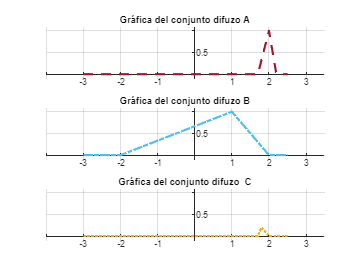

$$ans = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{5} & \frac{1}{10} & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

%Se definen los conjuntos A2 y B2 para el ejemplo
%Se define una varibale simbolica
syms x2;

%Definimos A2 por partes
A2 = piecewise(x2<=1.7,0,1.7<x2 & x2<=2,(x2-1.7)./(2-1.7),2<x2 & x2<=2.2,(2.2-x2)./(2.2-2),2.2<x2,0);

%Definimos B2 por partes
B2 = piecewise(x2<=-2,0,-2<x2 & x2<=1,(x2-(-2))./(1-(-2)),1<x2 & x2<=2,(2-x2)./(2-1),2<x2,0);

%Sustituimos los valores y guardamos
A3 = subs(A2,x2,[-3:0.1:2.5]);
B3 = subs(B2,x2,[-3:0.1:2.5]);
x3=-3:0.1:2.5;
%Se manda a llamar la función para cada caso
p05(x3,A3,B3,1)

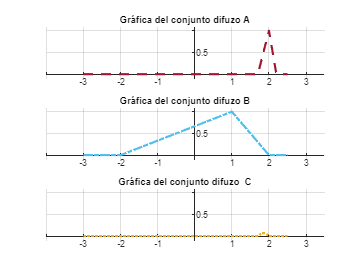

$$ans = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{15} & \frac{1}{15} & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

p05(x3,A3,B3,2)

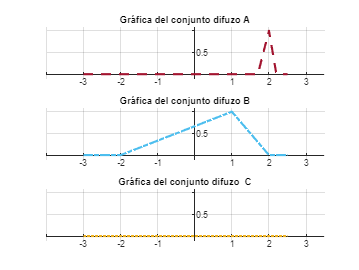

$$ans = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

p05(x3,A3,B3,3)

### **Problema 6**

Elabora una función que reciba el conjunto dominio x, el rango A, el rango B, de dos conjunto difusos. Un parámetro adicional que indique el tipo de unión que se quiere hacer (máximo, suma algebraica, suma acotada). La función debe regresar el rango de valores del conjunto resultante C. Además de imprimir una figura (3 por 1) donde se muestren las grafica de los tres conjunto involucrados.

Prueba esta función con el inciso d) de la imagen 4 (OperDif4). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso. Para esto:

- Reporta los tres tipos de uniones

- Combina las herramientas que ya tienes desarrolladas (de ser posible) para mostrar una gráfica con los tres tipos de uniones o desarrolla esta gráfica sin utilizar tus herramientas

En esta sección se espera tres llamadas a la función y un código para generar la cuarta gráfica. 

txt = "maximo"

C =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


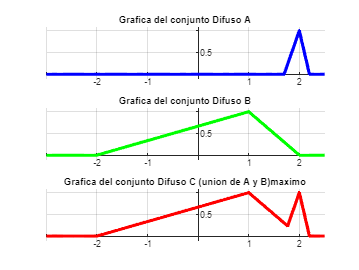

C1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x=-3:0.01:2.5;
A=trimf(x,[1.7 2 2.2]);
B=trimf(x,[-2 1 2]);
C1=p06(x,A,B,1)

txt = "suma algebraica"

C =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


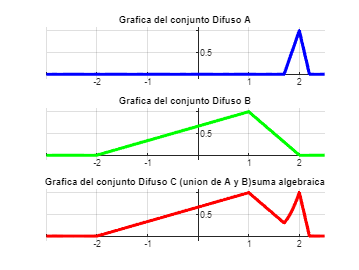

C2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


C2=p06(x,A,B,2)

txt = "suma acotada"

C =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


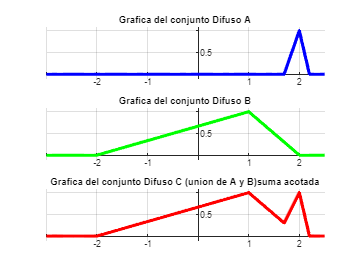

C3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


C3=p06(x,A,B,3)

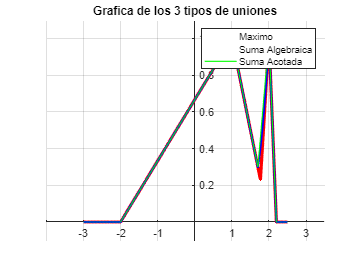


figure
hold on
plot(x,C1,'LineWidth',3,'Color','r')
plot(x,C2,'LineWidth',2,'Color','b')
plot(x,C3,'LineWidth',1,'Color','g')
grid on
axis([x(1)-1, x(end)+1,-0.1,1.1])
title('Grafica de los 3 tipos de uniones')
legend('Maximo','Suma Algebraica','Suma Acotada')
h=gca;
h.XAxisLocation = "origin";         
h.YAxisLocation = "origin";          

h.Box = "off";

### **Problema 7**

Resuleve el problema 4 para conjuntos en tiempo discreto. Prueba esta función con el inciso a) de la imagen 5 (OperDif5). 

clear 
clc
% Definimos el dominio 
x=1:0.5:3;
%Definimos el Rango
A=[1 0.75 0.3 0.15 0]

A =     1.0000    0.7500    0.3000    0.1500         0


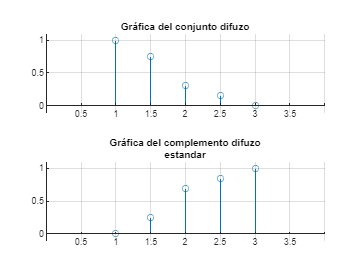

c1 =          0    0.2500    0.7000    0.8500    1.0000


%Llamamos a la funcion 
% El tercer parametro es el tipo de complemento: estandar, sugeno y yeger
% respectivamente
c1=complementoDifusoDis(x,A,1)

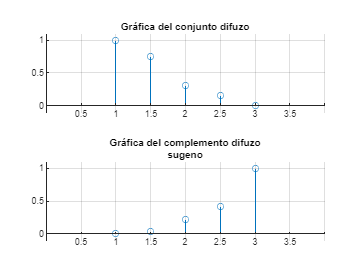

c2 =          0    0.0400    0.2258    0.4146    1.0000


c2=complementoDifusoDis(x,A,2,7)

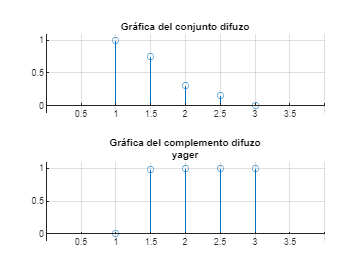

c3 =          0    0.9797    1.0000    1.0000    1.0000


c3=complementoDifusoDis(x,A,3,7)

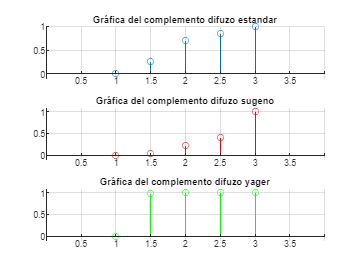

%%
% Para el siguiente punto.

e=1.-A;

su=((1.-A)./(1.+(7.*A)));

y=(1-(A.^7)).^(1/7);

figure

subplot(3,1,1)
        stem(x, e)
        grid on
        axis([min(x)-1,max(x)+1,-0.1,1.])
        title('Gráfica del complemento difuzo estandar')
        h = gca;                             % ejes actuales
        h.XAxisLocation = "origin";          % eje en el origen
        h.YAxisLocation = "origin";          % eje en el origen
        h.Box = "off"; 

subplot(3,1,2)
        stem(x, su,"r")
        grid on
        axis([min(x)-1,max(x)+1,-0.1,1.1])
        title("Gráfica del complemento difuzo sugeno")
        h = gca;                             % ejes actuales
        h.XAxisLocation = "origin";          % eje en el origen
        h.YAxisLocation = "origin";          % eje en el origen
        h.Box = "off"; 

subplot(3,1,3)
        stem(x, y,"g")
        grid on
        axis([min(x)-1,max(x)+1,-0.1,1.1])
        title("Gráfica del complemento difuzo yager")
        h = gca;                             % ejes actuales
        h.XAxisLocation = "origin";          % eje en el origen
        h.YAxisLocation = "origin";          % eje en el origen
        h.Box = "off"; 

### **Problema 8**

Resuleve el problema 5 para conjuntos en tiempo discreto. Prueba esta función con el inciso c) de la imagen 5 (OperDif5). 


x=1:0.5:3;
A=[1 0.75 0.3 0.15 0]

A =     1.0000    0.7500    0.3000    0.1500         0


B=[1 0.6 0.2 0.1 0]

B =     1.0000    0.6000    0.2000    0.1000         0


txt = "minimo"

C =     1.0000    0.6000    0.2000    0.1000         0


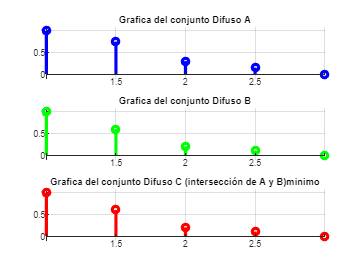

C1 =     1.0000    0.6000    0.2000    0.1000         0


C1=p08dis(x,A,B,1)

txt = "producto algebraico"

C =     1.0000    0.4500    0.0600    0.0150         0


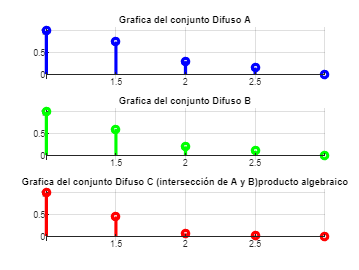

C2 =     1.0000    0.4500    0.0600    0.0150         0


C2=p08dis(x,A,B,2)

txt = "producto acotado"

C =     1.0000    0.3500         0         0         0


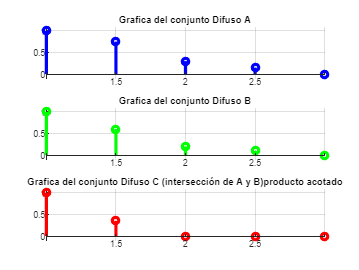

C3 =     1.0000    0.3500         0         0         0


C3=p08dis(x,A,B,3)

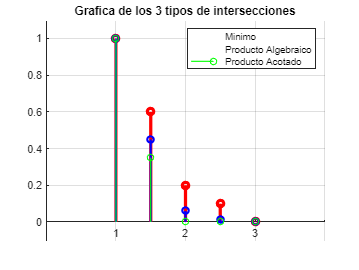


figure
hold on
stem(x,C1,'LineWidth',3,'Color','r')
stem(x,C2,'LineWidth',2,'Color','b')
stem(x,C3,'LineWidth',1,'Color','g')
grid on
axis([x(1)-1, x(end)+1,-0.1,1.1])
title('Grafica de los 3 tipos de intersecciones')
legend('Minimo','Producto Algebraico','Producto Acotado')
h=gca;
h.XAxisLocation = "origin";         
h.YAxisLocation = "origin";          

h.Box = "off";

### **Problema 9**

Resuleve el problema 6 para conjuntos en tiempo discreto. Prueba esta función con el inciso d) de la imagen 5 (OperDif5). 


x=1:0.5:3;
A=[1 0.75 0.3 0.15 0]

A =     1.0000    0.7500    0.3000    0.1500         0


B=[1 0.6 0.2 0.1 0]

B =     1.0000    0.6000    0.2000    0.1000         0


txt = "maximo"

C =     1.0000    0.7500    0.3000    0.1500         0


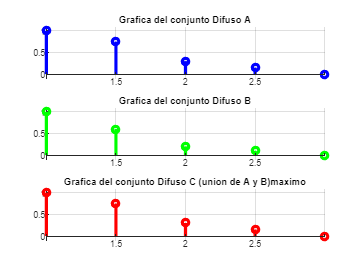

C1 =     1.0000    0.7500    0.3000    0.1500         0


C1=p09(x,A,B,1)

txt = "suma algebraica"

C =     1.0000    0.9000    0.4400    0.2350         0


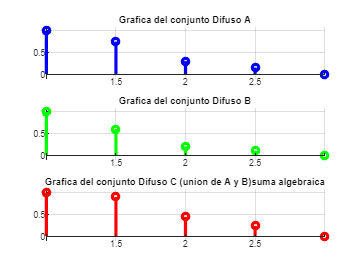

C2 =     1.0000    0.9000    0.4400    0.2350         0


C2=p09(x,A,B,2)

txt = "suma acotada"

C =     1.0000    1.0000    0.5000    0.2500         0


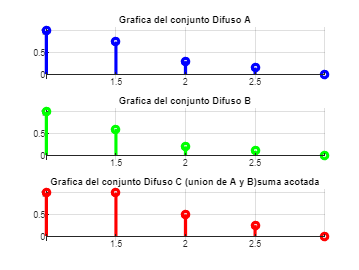

C3 =     1.0000    1.0000    0.5000    0.2500         0


C3=p09(x,A,B,3)

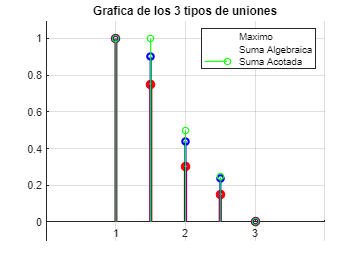


figure
hold on
stem(x,C1,'LineWidth',3,'Color','r')
stem(x,C2,'LineWidth',2,'Color','b')
stem(x,C3,'LineWidth',1,'Color','g')
grid on
axis([x(1)-1, x(end)+1,-0.1,1.1])
title('Grafica de los 3 tipos de uniones')
legend('Maximo','Suma Algebraica','Suma Acotada')
h=gca;
h.XAxisLocation = "origin";         
h.YAxisLocation = "origin";          

h.Box = "off";

### **Problema 10**

Implemente tres funciones,  para calcular las siguientes funciones de membresia

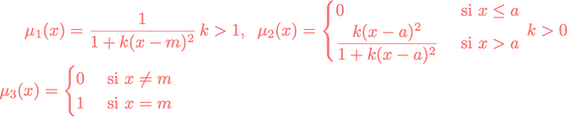

Los párametros que no muestras restricción pueden tener cualquier numero real como argumento, la función debe ser capaz de evaluar vectores de cualquier dimensión. La función $\mu_3
$ recibe el nombre de singleton

Grafique las funciones para los siguintes parámetros (con las herramientas ya construidas)

(a) $$\mu_1(x)\,con \, m=1,\,k=2$, (b) $\mu_1(x)\,con \, m=2,\,k=4$$


$$(c) \mu_2(x)\,con\, a=1,\,k=2, (d) \mu_2(x)\,con\, a=2\,k=4$$



$$(e) \mu_3(x)\,con\, m=2$$


Para ello proponga el dominio x. Se esperan 5 gráficas con el código correspndiente para generarlas.

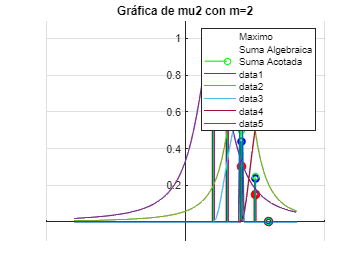

clear
clc
% Se da el dominio
x=-4:0.1:4;
%inciso a) M1 con m=1 y k=2
plot(x, mu1(x,2,1))
        grid on
        axis([min(x)-1,max(x)+1,-0.1,1.1])
        title("Gráfica de mu1 con m=1 y k=2")
        h = gca;                             % ejes actuales
        h.XAxisLocation = "origin";          % eje en el origen
        h.YAxisLocation = "origin";          % eje en el origen
        h.Box = "off"; 

        %inciso b) M1 con m=2 y k=4
plot(x, mu1(x,4,2))
        grid on
        axis([min(x)-1,max(x)+1,-0.1,1.1])
        title("Gráfica de mu1 con m=2 y k=4")
        h = gca;                             % ejes actuales
        h.XAxisLocation = "origin";          % eje en el origen
        h.YAxisLocation = "origin";          % eje en el origen
        h.Box = "off";

        %inciso c) M2 con a=1 y k=2
plot(x, mu2(x,2,1))
        grid on
        axis([min(x)-1,max(x)+1,-0.1,1.1])
        title("Gráfica de mu2 con a=1 y k=2")
        h = gca;                             % ejes actuales
        h.XAxisLocation = "origin";          % eje en el origen
        h.YAxisLocation = "origin";          % eje en el origen
        h.Box = "off";

        %inciso d) M2 con a=2 y k=4
plot(x, mu2(x,4,2))
        grid on
        axis([min(x)-1,max(x)+1,-0.1,1.1])
        title("Gráfica de mu2 con a=2 y k=4")
        h = gca;                             % ejes actuales
        h.XAxisLocation = "origin";          % eje en el origen
        h.YAxisLocation = "origin";          % eje en el origen
        h.Box = "off";
        %inciso e) M3 con m=2
plot(x, mu3(x,2))
        grid on
        axis([min(x)-1,max(x)+1,-0.1,1.1])
        title("Gráfica de mu2 con m=2")
        h = gca;                             % ejes actuales
        h.XAxisLocation = "origin";          % eje en el origen
        h.YAxisLocation = "origin";          % eje en el origen

        h.Box = "off";

### **Problema 11**

Implemente una gráfica donde indique ejemplos especificos para ilustrar

 

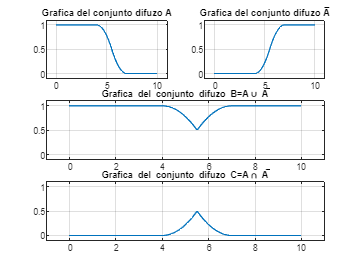

x=0:0.1:10;
fm= evalmf(fismf('zmf',[4,7]),x);
figure;

subplot(3,2,1)
plot(x,fm)
grid("on");
axis([-1 11 -0.1 1.1]);
title('Grafica del conjunto difuzo A')

subplot(3,2,2)
plot(x,1-fm)
grid("on");
axis([-1 11 -0.1 1.1]);
title('Grafica del conjunto difuzo A̅')

subplot(3,2,[3 4])
plot(x,max(fm,(1-fm)))
grid("on");
axis([-1 11 -0.1 1.1]);
title('Grafica del conjunto difuzo B=A\cup A̅')

subplot(3,2,[5 6])
plot(x,min(fm,(1-fm)))
grid("on");
axis([-1 11 -0.1 1.1]);
title('Grafica del conjunto difuzo C=A\cap A̅')

### **Problema 12**

Escoja tres conjuntos difusos $A,B,C$ con dominuo continuo. La elección debe ser de tal forma que la itersección de B con A y de B con C sea no vacia (esto solo es solo para visulizar la operación, y solo para eso)

 verifique las siguientes propiedades

 

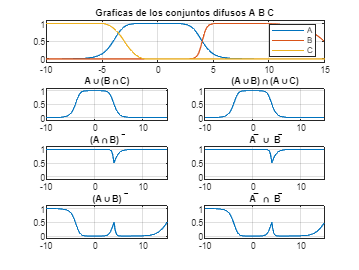

clear
clc
x=-10:0.1:15;
A= evalmf(fismf('gbellmf',[4,4,0]),x);
B= evalmf(fismf('dsigmf',[5,4,1,15]),x);
C= evalmf(fismf('zmf',[-5,-1]),x);
figure;

subplot(4,2,[1 2])
plot(x,A)
axis([-10 15 -0.1 1.1]);
hold on
plot(x,B)
plot(x,C)
legend('A','B','C')
hold off
grid on
title('Graficas de los conjuntos difusos A B C')
%--------------------------------------------------
subplot(4,2,3)
plot(x,max(A,min(B,C)))
axis([-10 15 -0.1 1.1]);
grid on
title('A\cup(B\capC)')

subplot(4,2,4)
plot(x,min(max(A,B),max(A,C)))
axis([-10 15 -0.1 1.1]);
grid on
title('(A\cupB)\cap(A\cupC)')
%--------------------------------------------------
subplot(4,2,5)
plot(x,(1-min(A,B)))
axis([-10 15 -0.1 1.1]);
grid on
title('(A\capB) ̅')

subplot(4,2,6)
plot(x,max((1-A),(1-B)))
axis([-10 15 -0.1 1.1]);
grid on
title('A̅ \cup B̅')
%--------------------------------------------------
subplot(4,2,7)
plot(x,(1-max(A,B)))
axis([-10 15 -0.1 1.1]);
grid on
title(' (A\cupB) ̅')

subplot(4,2,8)
plot(x,min((1-A),(1-B)))
axis([-10 15 -0.1 1.1]);
grid on
title('A̅ \cap B̅')

### Bibliografia

-  Zadeh, L. (1965). Fuzzy sets. Information and Control 8(3), 338–353.

- MathWorks. (s. f.). *smf*. la.mathworks.com. Recuperado 17 de septiembre de 2022, de [https://la.mathworks.com/help/fuzzy/smf.html](https://la.mathworks.com/help/fuzzy/smf.html)

- MathWorks. (s. f.-a). *sigmf*. la.mathworks.com. Recuperado 17 de septiembre de 2022, de https://la.mathworks.com/help/fuzzy/sigmf.html